# **This Script Allows Data Sorting and Plot The Temperature Distribution in a Specific Grid.**

%         "--------------------------------------------------------------------------"
%         " MATLAB Script: TTM_Grid_Datasort_Graphplot"
%         "--------------------------------------------------------------------------"
%         ""
%         " File: TTM_Grid_Datasort_Graphplot.mlx"
%         " Description: This script demonstrates a MATLAB Code."
%         " Author: Shorup Chanda"
%         " Created: 2023-08-11"
%         " Last Modified: 2023-08-11"
%         ""
%         " Copyright Notice:"
%         " (c) 2023 Shorup Chanda. All rights reserved."
%         " This code may not be used or distributed without permission."
%         ""
%         "--------------------------------------------------------------------------"

**Input your Grid Number and Ranges Here: **

% Specify the the grid you want to select
Grid = 38; %Enter Grid Number+1 due to start from 0
startCol = 1;
endCol = 6;

%Specify the timestep for last column
p = 500; %first data
q = 500; %difference between consequtive data
r = 20000; %last data

#### Define Folder Path

% Define the folder where your files are located
folderPath = 'L:\1_ProjectWorks\MOLECULARDYNAMICS\Lammpscodesubuntu\laser ttm\TTM_sphere\1';

#### This Sort files according to TImesteps

% Get a list of all files in the folder with a .txt extension
fileList = dir(fullfile(folderPath, 'T_out.*.txt'));
[~,idx] = sort([fileList.datenum]);
fileList = fileList(idx);

#### Build Matrix of the files & data 

% Initialize a cell array to store the Rows
matrices = cell(1, numel(fileList));
% Loop through each file and load its content as a matrix
for i = 1:numel(fileList)
    filePath = fullfile(folderPath, fileList(i).name);
    
    % Read the file's contents as lines
    fileLines = fileread(filePath);
    
    % Split the lines into a cell array
    lines = strsplit(fileLines, '\n');
    
    % Remove the first line
    lines(1) = [];
    
    % Combine the lines back into a single string
    cleanedFileContent = strjoin(lines, '\n');
    
    % Convert the cleaned content to a matrix
    data = str2num(cleanedFileContent);
    
    matrices{i} = data;  % Store the loaded data as a matrix
end

#### This part is done to create a complete table including thermo steps

% Initialize a cell array to store the selected grids
selectedGrids = cell(1, numel(matrices));

% Loop through each matrix and select the desired grid
for i = 1:numel(matrices)
    selectedGrids{i} = matrices{i}(Grid, startCol:endCol);
end

% Combine the selected grids into a single matrix
numFiles = numel(selectedGrids);
gridSize = size(selectedGrids{1});
combinedMatrix = zeros(gridSize(1) * numFiles, gridSize(2));

% Populate the new matrix with selected grids' data
for i = 1:numFiles
    rowRange = (i - 1) * gridSize(1) + 1 : i * gridSize(1);
    combinedMatrix(rowRange, :) = selectedGrids{i};
end

% Define another matrix variable using the data from combinedMatrix
anotherMatrix = combinedMatrix;
% Create a new column with data ranging from 500 to 20000 in equal increments
newColumnData = (p:q:r)';
% Append the new column to the anotherMatrix variable
anotherMatrix = [anotherMatrix, newColumnData];

% Set the display format to fixed-point with a specified number of decimal places
format bank; % Change 'bank' to the look good format of decimal places
copyrightInfo = createCopyrightInfo();
disp(copyrightInfo);

    "--------------------------------------------------------------------------"
    " MATLAB Script: TTM_Grid_Datasort_Graphplot"
    "--------------------------------------------------------------------------"
    ""
    " File: TTM_Grid_Datasort_Graphplot.mlx"
    " Description: This script demonstrates a MATLAB Code."
    " Author: Shorup Chanda"
    " Created: 2023-08-11"
    " Last Modified: 2023-08-11"
    ""
    " Copyright Notice:"
    " (c) 2023 Shorup Chanda. All rights reserved."
    " This code may not be used or distributed without permission."
    ""
    "--------------------------------------------------------------------------"



% Display the combined matrix
disp(anotherMatrix);

         37.00             0             0       2314.21        349.77             0        500.00
         37.00             0             0       4510.72        454.30             0       1000.00
         37.00             0             0       5462.79        626.96             0       1500.00
         37.00             0             0       5170.67        796.95             0       2000.00
         37.00             0             0       4801.40        954.71             0       2500.00
         37.00             0             0       4607.99       1061.44             0       3000.00
         37.00             0             0       4490.43       1143.10             0       3500.00
         37.00             0             0       4402.76       1242.82             0       4000.00
         37.00             0             0       4326.62       1270.79             0       4500.00
         37.00             0             0       4259.51       1326.27             0       5000.00
         3

#### This part is done to plot the distribution curves

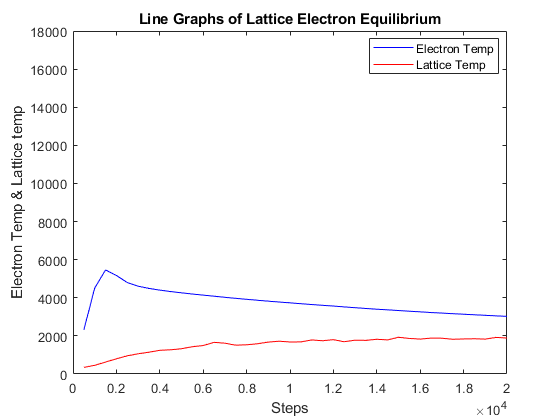

% Extract column 4 (X-axis), column 5, and column 7 (Y-axis)
xData = anotherMatrix(:, 7);
yData1 = anotherMatrix(:, 4);
yData2 = anotherMatrix(:, 5);

% Create a line graph of column 4 vs column 7
figure;
plot(xData, yData1, '-b', 'DisplayName', 'Electron Temp');
hold on;

% Create a line graph of column 7 vs column 5
plot(xData, yData2, '-r', 'DisplayName', 'Lattice Temp');

xlabel('Steps');
ylabel('Electron Temp & Lattice temp');
title ('Line Graphs of Lattice Electron Equilibrium');
legend('Location', 'best');

hold off; % Release the hold on behavior

xlim([0 20000])
ylim([0 18000])

#### Copyright Notice of the Created Script

function info = createCopyrightInfo
info = [
    "--------------------------------------------------------------------------"
    " MATLAB Script: TTM_Grid_Datasort_Graphplot"
    "--------------------------------------------------------------------------"
    ""
    " File: TTM_Grid_Datasort_Graphplot.mlx"
    " Description: This script demonstrates a MATLAB Code."
    " Author: Shorup Chanda"
    " Created: 2023-08-11"
    " Last Modified: 2023-08-11"
    ""
    " Copyright Notice:"
    " (c) 2023 Shorup Chanda. All rights reserved."
    " This code may not be used or distributed without permission."
    ""
    "--------------------------------------------------------------------------"
    ];
end